We look at the balance between the axial spring and the magnet to lock the claw in position axially

clear
clf

considering a constant spring constant we get the pull of one **axial spring** from SODEMANN

k_axial = 0.29e3; % N/mm --> N/m % max kraft 47,43, max vandring 140,97, total lenth 229,87
% varenummer 	E07500633500S trækfjeder SODEMANN
x_axial = 140e-3; % udspændt fjeder til træk af claw
F_spring_axial = k_axial * x_axial

F_spring_axial = 40.6000

Magnet axial lock force

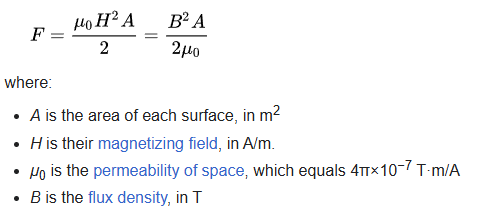

https://en.wikipedia.org/wiki/Force_between_magnets

g = 9.82;
x_contact = 1.85e-4; % "contact" point between the magnets (closest point)
d_magnet = 27e-3; %diameter of magnet
%chrome-extension://efaidnbmnnnibpcajpcglclefindmkaj/https://www.supermagnete.dk/data_sheet_CS-S-27-04-N.pdf
r_magnet = d_magnet/2; %radius of magnet
L = 4e-3; % https://www.supermagnete.dk/magneter-til-at-skrue-pa/skivemagnet-27mm-hjde-4mm_CS-S-27-04-N?group=lp-screwable-magnets
A = pi*(d_magnet/2)^2 %area of magnet surface

A = 5.7256e-04

mu = 1.25663706e-6; %(T·m)/A). Magnetic permability of air

kgF = 8; %kg  % the carry force of the magnet

We find an equation for the force of the magnetic field x distance away

syms B
F_magnet_in = kgF * g% / (1 + x_contact^2)

F_magnet_in = 78.5600

F_eq = F_magnet_in == B^2 * A / (2*mu); % force at contact point

B_sol = solve(F_eq, B);
B = double(B_sol(2))

B = 0.5872


x=x_contact

x = 1.8500e-04


F_magnet1 = ((B^2 * A^2 * (L^2 * r_magnet^2)) / (pi * mu * L^2)) * ...
    ( 1 / x^2 + 1 / (x+2*L)^2 - 2/(x+L)^2) %force between the two magnets

F_magnet1 = 151.9655

Frication acting on the calw is devided in to two kinds that are added up.

- Due to gravity we find

m_claw = 1; %kg <--------- differ between claws
f_s = 0.20; %static / kinetic friction coeffecient %steel on steel
F_claw_fric = g * m_claw * f_s

F_claw_fric = 1.9640

We sum the forces and add them

syms F_n_x
F_n_x_eq = 0 == F_spring_axial - F_magnet1 - F_claw_fric + F_n_x;

F_n_x_sol = solve(F_n_x_eq, F_n_x);
F_n_x_sol = double(F_n_x_sol)

F_n_x_sol = 113.3295

## plot

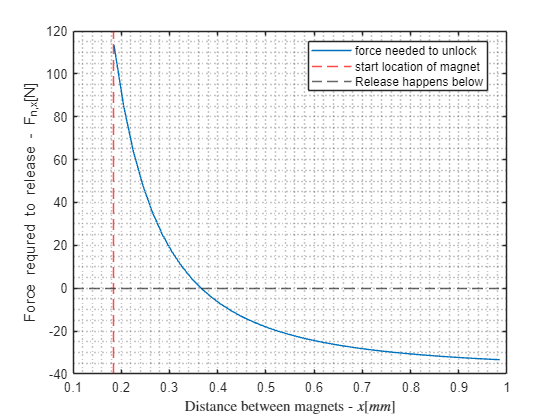

syms F_n_x
x_slut = 1e-3;
xs = x_contact:2e-5:x_slut; %Distance between magnets
for i = 1:length(xs)  
    F_magnet = ((B^2 * A^2 * (L^2 * r_magnet^2)) / (pi * mu * L^2)) *... 
    ( 1 / xs(i)^2 + 1 / (xs(i)+2*L)^2 - 2/(xs(i)+L)^2);

    x_axial = 140e-3 - xs(i); % udspændt fjeder til træk af claw
    F_spring_axial = k_axial * x_axial;

    F_n_x_eq = 0 == F_spring_axial - F_magnet - F_claw_fric + F_n_x;
    F_n_x_sol = solve(F_n_x_eq, F_n_x);

    F_n_x_sols(i) = double(F_n_x_sol);
    F_magnets(i) = F_magnet; % for later use
end

plot(xs*1000, F_n_x_sols, DisplayName="force needed to unlock")
hold on

xline(x_contact*1000,'r--', DisplayName="start location of magnet")
yline(0,'--', DisplayName="Release happens below")
xlabel("Distance between magnets - $x [mm]$", Interpreter="latex")
ylabel("Force requred to release - F_{n,x}[N]")
grid("minor")
legend(location='best')
hold off

**Release force**

phi = 45; % angle on claw slope

n_stack = 2; %number of stacked disc springs for more force
F_realese = 553 * n_stack; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s = 0.53e-3;
% tallerken fjeder vare nummer 1800-620-70

F_realease_x = sind(phi) * F_realese

F_realease_x = 782.0601


% T = F_realese * r
W = F_realese * s % The work the spring does on the rotor

W = 0.5862


syms omega
% I = 1; % inertia of the test motor % HMC4 355L-2
I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-2
% I = 15.9356; % inertia of the test motor % HMC4 355L-2 <--------- differ from motor to motor
W_eq = W == 1/2 * I * omega^2; % work of the rotor
omega_sol = solve(W_eq, omega);
omega = double(omega_sol(2))

omega = 0.5644

Dermed har jeg hastigheden ved slip, kraften aftager løbende i fjederen men antage at være tæt på F_realease_x i det kontakten slippes.

Couplings delen skal rejse 1 mm og tabet her negligeres

We see this as a totallly non-elastic collision because of the slow speeds and high moments of inertia.

m_rotor = 500; %                 <--------- differ from motor to motor
r = 0.1;%
u_rotor = r * omega

u_rotor = 0.0564

u_rotor_x = sind(phi) * u_rotor

u_rotor_x = 0.0399

% where u_claw = 0 since we are seeing it from the claws point of veiw.
v_claw_x = m_rotor * u_rotor_x / (m_rotor + m_claw) 

v_claw_x = 0.0398


F_claw = m_claw * v_claw_x

F_claw = 0.0398

F_rotor = m_rotor * v_claw_x

F_rotor = 19.9156


F_move = (F_spring_axial - F_magnet1 - F_claw_fric + F_claw)

F_move = -113.5754

The magnet is too powerfull and no moment is seen. The small force applied by the claw requires too large of a balance.


x_axial_move =x_slut; % 
E_kin_claw = 1/2 * m_claw * v_claw_x^2

E_kin_claw = 7.9326e-04


% E_kin_claw = F_claw*s
s_claw = E_kin_claw/F_move

s_claw = -6.9845e-06


E_axial_spring = 1/2 * k_axial * (x_axial_move)^2 * 2 %two springs %

E_axial_spring = 2.9000e-04


Friction_work_done = F_claw_fric * x_axial_move

Friction_work_done = 0.0020

Magnetic_work_done = trapz(xs, F_magnets) % trapezoidal integration with matlab function

Magnetic_work_done = 0.0226

% Work done due to friction

Total = E_kin_claw + E_axial_spring - Magnetic_work_done - Friction_work_done

Total = -0.0235